% 1. Definite Integral, Trapezoidal Formula

n_values = 100:50:5000;
totals = zeros(length(n_values), 1);
for i = 1:length(n_values)
    n = n_values(i);
    totals(i) = TRAPsolver(n);
end

figure
plot(n_values, totals)
xlabel("n value")
ylabel("estimated value")
title("estimated integral values with trapezoidal approximation")

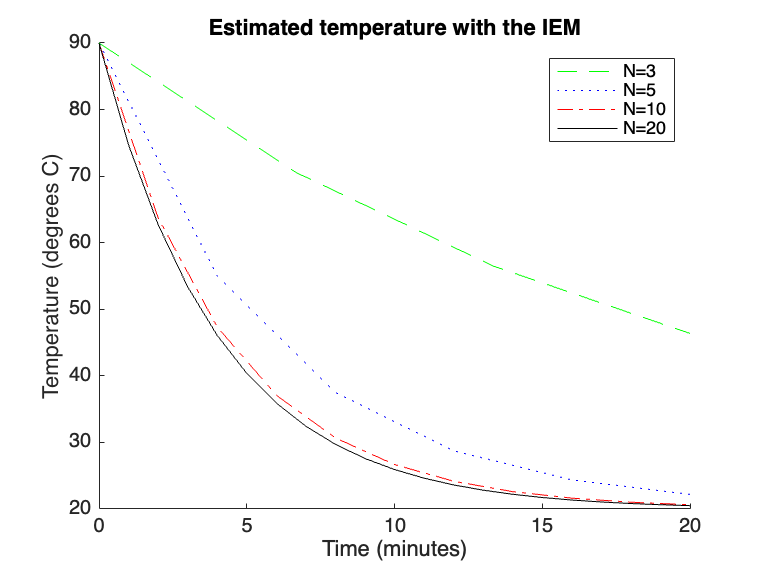


% 2. 1st order DE, rate of cooling

[t_3, temp_3] = IEMSolver(3);
[t_5, temp_5] = IEMSolver(5);
[t_10, temp_10] = IEMSolver(10);
[t_20, temp_20] = IEMSolver(20);

figure
hold on
plot(t_3, temp_3, "--g")
plot(t_5, temp_5, ":b")
plot(t_10, temp_10, "-.r")
plot(t_20, temp_20, "-k")
legend("N=3", "N=5", "N=10", "N=20")
xlabel("Time (minutes)")
ylabel("Temperature (degrees C)")
title("Estimated temperature with the IEM")

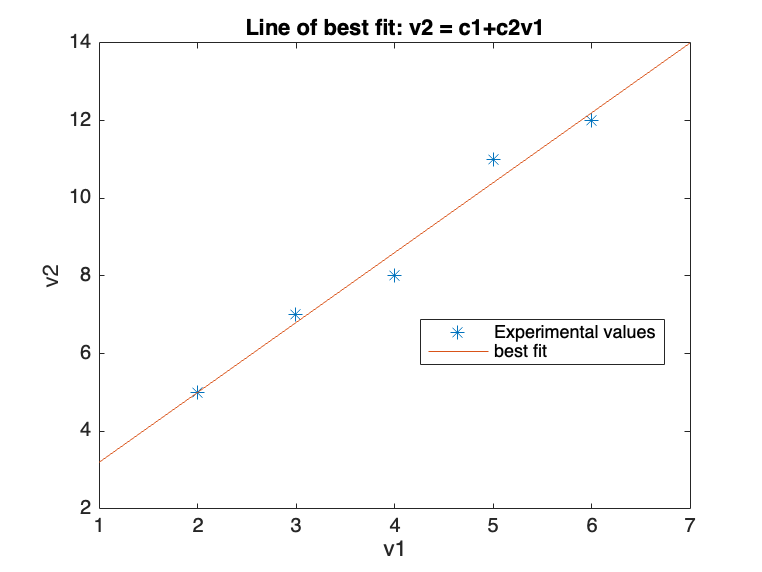


% 3. least squares, experiment

v1 = [2 3 4 5 6];
v2 = [5 7 8 11 12];
A = [ones(5, 1) v1'];
b = v2';
[c1, c2] = LSsolver(A, b);

x = linspace(1, 7);
lin_func = c1+c2*x;

figure
plot(v1, v2, '*')
hold on
plot(x, lin_func)
legend("Experimental values", "best fit", "location", "best")
xlabel("v1")
ylabel("v2")
title("Line of best fit: v2 = c1+c2v1")

function value = TRAPsolver(n)
    start_x = 0;
    end_x = 30;
    dx = (end_x-start_x)/n;
    x_values = start_x:dx:end_x;
    y_values = 200.*(x_values./(5 + x_values)).*exp(-2.*x_values./30);
    value = 0;
    for j = 2:length(x_values)
        value = value + dx*0.5*(y_values(j)+y_values(j-1));
    end
end

function [t, T] = IEMSolver(N)
    k = 0.25;
    T_a = 20;
    T_0 = 90;
    t_start = 0;
    t_end = 20;
    dt = (t_end-t_start)/N;
    t = t_start:dt:t_end;
    SOL = NaN(1, length(t));
    SOL(1) = T_0;
    for j = 2:length(t)
        sL = -1*k*(SOL(j-1)-T_a);
        sR = -1*k*((SOL(j-1)+dt*sL)-T_a);
        SOL(j) = SOL(j-1)+dt*0.5*(sL+sR);
    end
    T = SOL(:);
end

function [c1, c2] = LSsolver(A, b)
    x_ls = A'*A\(A'*b);
    c1 = x_ls(1);
    c2 = x_ls(2);
end